## Plots of gaze change per object

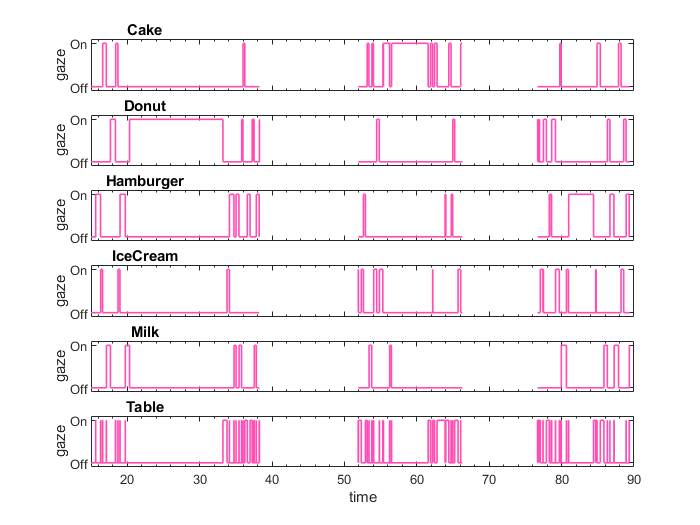

warning('off', 'all')
fc_full = readtable('Gaze_Data1.csv');
supp_data = readtable('Supp_File1.csv');
warning('on', 'all')
objectIDManual = {'Table','Sphere','Cube','Cylinder','Capsule'};
objectIDs = unique(fc_full.Object);
objectIDs = objectIDs(~cellfun('isempty',objectIDs));
minx = floor(min(fc_full.Time));
maxx = ceil(max(fc_full.Time));
tiledlayout(length(objectIDs),1);
time = [minx; fc_full.Time;maxx];
for i = 1:length(objectIDs)-1
    %temp = fc_full(strcmp(fc_full.Object,objectIDs(i,1)),:);
    tempFocus = strcmp(fc_full.Object,objectIDs(i,1));
    tempFocus = [0;tempFocus;0];
    nexttile
    stairs(time, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])     
    set(gca, "XLabel",[],'XTickLabel',[],'XMinorTick',"on",'XLim',[minx maxx],...
        "ytick",[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
    ylabel('gaze')
    title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])    
end
i = length(objectIDs);
temp = fc_full(strcmp(fc_full.Object,objectIDs(i,1)),:);    
tempFocus = strcmp(fc_full.Object,objectIDs(i,1));
tempFocus = [0;tempFocus;0];
nexttile
stairs(time, tempFocus, 'LineWidth', 1, "Color",[1 0.3 0.7])
set(gca, 'XMinorTick',"on",'XLim',[minx maxx],...
    'Ytick',[0 1],'YTickLabel',{'Off', 'On'},'YLim',[-0.1 1.1])
xlabel('time')
ylabel('gaze')
title(objectIDs(i,1), 'units', 'normalized', 'position', [0.1 1])
hold off

## fixation calculations

fixationThreshold = 0.1; %100 ms fixation threshold

%calculate total viewing time per viewing: time end viewing - time begin
%viewing
viewingTimes = zeros(2*size(unique(fc_full.Trial),1),1);
tempStartTime = fc_full.Time(1);
j=1;
for i = 2:height(fc_full) 
    if fc_full.ViewNo(i) ~= fc_full.ViewNo(i-1)
        tTime = fc_full.Time(i-1)-tempStartTime;
        viewingTimes(j,1) = tTime;
        tempStartTime = fc_full.Time(i); %set new start time
        j = j+1;
    end
end
viewingTimes = viewingTimes(~isnan(viewingTimes)); %each pair of rows are 2 viewing phases for each trial



%create new table for fixation data by each fixation, without collision
%point coordinates, with centroid coordinates, and with extra column for number of gaze
%points per fixation
fixationData = [fc_full array2table(zeros(height(fc_full),1))]; 

% %set first row to empty - because fixation data will populate at end of
% fixation time (so can't be in first row)
for i = 1:width(fixationData)    
    if iscell(fixationData(1,[i]).(1))
        fixationData(1,[i]).(1) = cell(1,1);
    else
        fixationData(1,[i]).(1) = 0;
    end
end

%%iterate through raw data to create new fixation table
tempStartTime = fc_full.Time(1); %variable start time to calculate fixation duration 
for i = 2:height(fc_full) %iterate from second gaze point onwards
    if fc_full.ViewNo(i) ~= fc_full.ViewNo(i-1) %if new viewing phase
        %populate previous row (i.e. last row of previous viewing phase) 
        % with fixation duration and details of object
        fixationData(i-1,[1]).(1) = fc_full.Time(i-1) - tempStartTime; 
        fixationData(i-1,[2]).(1) = fc_full.Object(i-1);
        fixationData(i-1,[3:8]) = fc_full(i-1, [3:8]);
        fixationData(i-1,[9]) = num2cell(mean(fc_full.ColX(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i-1,[10]) = num2cell(mean(fc_full.ColY(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i-1,[11]) = num2cell(mean(fc_full.ColZ(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i-1,[21]) = num2cell(size(fc_full.ColZ(find(tempStartTime==fc_full.Time):i-1),1));
        tempStartTime = fc_full.Time(i); %set new start of fixation
        %repopulate remaining columns
        fixationData(i-1,[12:20])=fc_full(i-1,[12:20]);
        %and empty current row
        for j = 1:width(fixationData)    
            if iscell(fixationData(i,[j]).(1))
                fixationData(i,[j]).(1) = cell(1,1);
            else
                fixationData(i,[j]).(1) = 0;
            end
        end        
    elseif strcmp(fc_full.Object(i), fc_full.Object(i-1))==false ...
            % if object is different from previous gaze point
        %populate row with fixation duration and details of object
        fixationData(i,[1]).(1) = fc_full.Time(i) - tempStartTime; 
        fixationData(i,[2]).(1) = fc_full.Object(i-1);
        fixationData(i,[3:8]) = fc_full(i-1, [3:8]);
        fixationData(i,[9]) = num2cell(mean(fc_full.ColX(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i,[10]) = num2cell(mean(fc_full.ColY(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i,[11]) = num2cell(mean(fc_full.ColZ(find(tempStartTime==fc_full.Time):i-1)));
        fixationData(i,[21]) = num2cell(size(fc_full.ColZ(find(tempStartTime==fc_full.Time):i-1),1));
        tempStartTime = fc_full.Time(i); %set new start of fixation
    else 
        %empty current row
        for j = 1:width(fixationData)    
            if iscell(fixationData(i,[j]).(1))
                fixationData(i,[j]).(1) = cell(1,1);
            else
                fixationData(i,[j]).(1) = 0;
            end
        end
    end
end


%set variable names and apply threshold of over 100ms
fixationData.Properties.VariableNames([1 9:11]) = ...
    {'Fix. Duration', 'CentrX','CentrY','CentrZ'};
fixationData.Properties.VariableNames([21]) = ...
    {'No. Gaze Pts'};
fixationData = fixationData(fixationData.("Fix. Duration")>fixationThreshold,:);


%create new table with higher-level fixation variable data
fixVariableNames = {'Fixation Count', 'Av. Fix. Duration', ...
    'Total Fix. Duration','Proportion of fixations', 'Proportion of fix. duration'};
fixationVariables = zeros(height(supp_data),(length(objectIDs)*6)+6);
sumFixCount = zeros(height(supp_data),1);
for i = 1:length(length(fixationVariables))
    for j = 1:length(objectIDs)
        temp = fixationData(strcmp(fixationData.Object,objectIDs(j,1)),:);
        %need to filter this by trial and view
        objectID = (6*j) - 2;
        fixCount = (6*j) - 1;
        AvFixDur = 6*j;
        TotFixDur = (6*j)+1;
        %fixationVariables(i,objectID) = temp.Object(1);
        fixationVariables(i,fixCount) = size(temp,1); % fixation Count
        sumFixCount(i) = sumFixCount(i) + fixationVariables(i,fixCount);
        fixationVariables(i,AvFixDur) = mean(temp.("Fix. Duration")); % mean fixation duration
        fixationVariables(i,TotFixDur) = sum(temp.("Fix. Duration")); % total fixation duration     
    end
end


for i = 1:length(length(fixationVariables))
    for j = 1:length(objectIDs)
        temp = fixationData(strcmp(fixationData.Object,objectIDs(j,1)),:);
        PropFix = (6*j)+2;
        PropFixDur = (6*j)+3;        
        fixationVariables(i,PropFix) = fixationVariables(i,fixCount)/sumFixCount(i);
        fixationVariables(i,PropFixDur) = fixationVariables(i,TotFixDur)/viewingTimes(i);
    end
end
%proportional calculations
% for i = 1:length(objectIDs)
%     fixationVariables(4,i) = fixationVariables(1,i)/...
%         nansum(fixationVariables(1,:)); % proportion of number of fixations to total number
%     fixationVariables(5,i) = fixationVariables(3,i)/...
%         sum(viewingTimes); %proportion of duration of fixations to total time
% end


for i = 1: length(objectIDs) %iterate per object
    temp = fixationData(strcmp(fixationData.Object,objectIDs(i,1)),:);
    fixationVariables(1,i) = size(temp,1); % fixation Count
    fixationVariables(2,i) = mean(temp.("Fix. Duration")); % mean fixation duration
    fixationVariables(3,i) = sum (temp.("Fix. Duration")); % total fixation duration     
end
%proportional calculations
for i = 1:length(objectIDs)
    fixationVariables(4,i) = fixationVariables(1,i)/...
        nansum(fixationVariables(1,:)); % proportion of number of fixations to total number
    fixationVariables(5,i) = fixationVariables(3,i)/...
        sum(viewingTimes); %proportion of duration of fixations to total time
end
% final touches to table and display
fixationVariables = array2table(fixationVariables);
fixationVariables.Properties.VariableNames = objectIDs;
fixationVariables.Properties.RowNames = fixVariableNames;
fixationVariables

fixationVariables = 5×6 table
                                    Cake       Donut     Hamburger    IceCream     Milk       Table 
                                   _______    _______    _________    ________    _______    _______

    Fixation Count                      14         10          12          11          10         16
    Av. Fix. Duration              0.32923    0.33984     0.44272     0.35343       0.443    0.37263
    Total Fix. Duration             4.6092     3.3984      5.3126      3.8877        4.43     5.9621
    Proportion of fixations        0.19178    0.13699     0.16438     0.15068     0.13699    0.21918
    Proportion of fix. duration     0.1582    0.11665     0.18235     0.13

## Object details

tableDiameter = 0.8;
tableX = unique(fc_full.PosX(strcmp(fc_full.Object, "Table")));
tableX = tableX(1,1);
tableZ = unique(fc_full.PosZ(strcmp(fc_full.Object, "Table")));
tableZ = tableZ(1,1);
%tableX = 0.0830; %X-centre of table for offsetting
%tableZ = 0.7171; %Z-centre of table for offsetting



## Plots

Gaze points - EVENTUALLY PUT PLOT CODE INTO FUNCTION

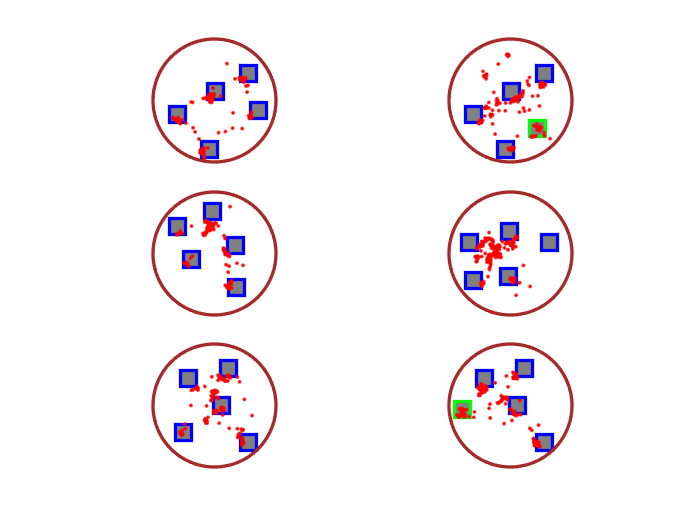

notTableL = ~(strcmp(fixationData.Object,"Table"));
%logical array for each view in each trial 
trial1L = fixationData.Trial==1;
view1L = fixationData.ViewNo==1;
tiledlayout(height(supp_data)/2,2, "TileSpacing","compact");

for i = 0:2:4
    for j = 1:2
        t = (i/2)+1; %trial number
        v = j; %view number
        k = i+j; %suppdata row
        nexttile
        trialL = fc_full.Trial==t;
        viewL = fc_full.ViewNo==v;
        combinedL = trialL & viewL;
        for o = 1:5 %objects
            hold on
            ID = (o*3) + 1; %index for objectID
            X = (o*3) + 2; %index for object X position
            Z = (o*3) + 3; %index for object Z position
            if strcmp(supp_data(k,ID).(1), supp_data.ObjShifted(k))
                plot(supp_data(k,X).(1), supp_data(k,Z).(1),'s',...
                'LineWidth',2,...
                'MarkerSize',12,...
                'MarkerEdgeColor','g',...
                'MarkerFaceColor',[0.5,0.5,0.5])
            else
                plot(supp_data(k,X).(1), supp_data(k,Z).(1),'s',...
            'LineWidth',2,...
            'MarkerSize',12,...
            'MarkerEdgeColor','b',...
            'MarkerFaceColor',[0.5,0.5,0.5])
            end            
        end
        hold on
        set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
            'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
        theta = linspace(0,2*pi);
        x = (tableDiameter/2)*cos(theta) + tableX;
        y = (tableDiameter/2)*sin(theta) + tableZ;
        plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
        plot(fc_full.ColX(combinedL), fc_full.ColZ(combinedL),'.r')
        axis equal
        
        axis off
    end
end

fixations proportional to number of gaze points/duration

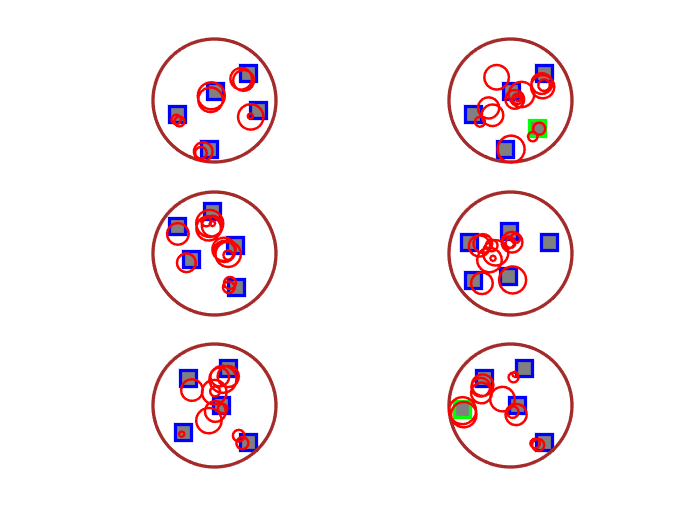


tiledlayout(height(supp_data)/2,2, "TileSpacing","compact");
for i = 0:2:4
    for j = 1:2
        t = (i/2)+1; %trial number
        v = j; %view number
        k = i+j; %suppdata row
        nexttile
        trialL = fixationData.Trial==t;
        viewL = fixationData.ViewNo==v;
        combinedL = trialL & viewL;
        for o = 1:5 %objects
            hold on
            ID = (o*3) + 1; %index for objectID
            X = (o*3) + 2; %index for object X position
            Z = (o*3) + 3; %index for object Z position
            if strcmp(supp_data(k,ID).(1), supp_data.ObjShifted(k))
                plot(supp_data(k,X).(1), supp_data(k,Z).(1),'s',...
                'LineWidth',2,...
                'MarkerSize',12,...
                'MarkerEdgeColor','g',...
                'MarkerFaceColor',[0.5,0.5,0.5])
            else
                plot(supp_data(k,X).(1), supp_data(k,Z).(1),'s',...
            'LineWidth',2,...
            'MarkerSize',12,...
            'MarkerEdgeColor','b',...
            'MarkerFaceColor',[0.5,0.5,0.5])
            end            
        end
        hold on
        set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
            'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
        theta = linspace(0,2*pi);
        x = (tableDiameter/2)*cos(theta) + tableX;
        y = (tableDiameter/2)*sin(theta) + tableZ;
        plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
        
        for f=1:numel(fixationData.CentrX(combinedL))
            fX = fixationData.CentrX(combinedL);
            fX = fX(f);
            fZ = fixationData.CentrZ(combinedL);
            fZ = fZ(f);            
            plot(fX,fZ,'ro',...
                 'MarkerSize',fixationData.("No. Gaze Pts")(f)/4,...
                 'LineWidth',1.5)
            hold on
        end
        axis equal
        
        axis off
    end
end

fixation markers proportional to fixations per object, vector markers between fixation markers

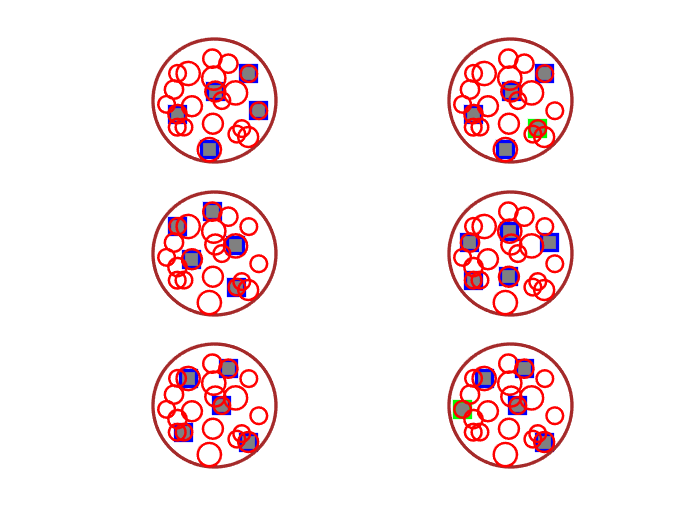

notTableLObjID = ~(strcmp(objectIDs,"Table"));
objectIDNoTable = objectIDs(notTableLObjID);
tiledlayout(height(supp_data)/2,2, "TileSpacing","compact");
for i = 0:2:4
    for j = 1:2
        t = (i/2)+1; %trial number
        v = j; %view number
        k = i+j; %suppdata row
        nexttile
        trialL = fixationData.Trial==t;
        viewL = fixationData.ViewNo==v;
        combinedL = trialL & viewL;
        for o = 1:5 %objects
            hold on
            ID = (o*3) + 1; %index for objectID
            X = (o*3) + 2; %index for object X position
            Z = (o*3) + 3; %index for object Z position
            if strcmp(supp_data(k,ID).(1), supp_data.ObjShifted(k))
                plot(supp_data(k,X).(1), supp_data(k,Z).(1),'s',...
                'LineWidth',2,...
                'MarkerSize',12,...
                'MarkerEdgeColor','g',...
                'MarkerFaceColor',[0.5,0.5,0.5])
            else
                plot(supp_data(k,X).(1), supp_data(k,Z).(1),'s',...
            'LineWidth',2,...
            'MarkerSize',12,...
            'MarkerEdgeColor','b',...
            'MarkerFaceColor',[0.5,0.5,0.5])
            end            
        end
        hold on
        set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
            'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
        theta = linspace(0,2*pi);
        x = (tableDiameter/2)*cos(theta) + tableX;
        y = (tableDiameter/2)*sin(theta) + tableZ;
        plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
        
        %plot fixation markers proportional to number of fixations per object
        for f = 1: length(objectIDNoTable) %iterate per object  
            temp = fixationData(combinedL);
            
            for h = 1:height(temp)
                plot(temp.PosX(h),temp.PosZ(h),'ro',...
              'MarkerSize',fixationVariables.(f)(1),...
              'LineWidth',1.5)
                hold on       
            end
        end
        axis equal
        
        axis off
    end
end

fixations proportional to number of gaze points/duration

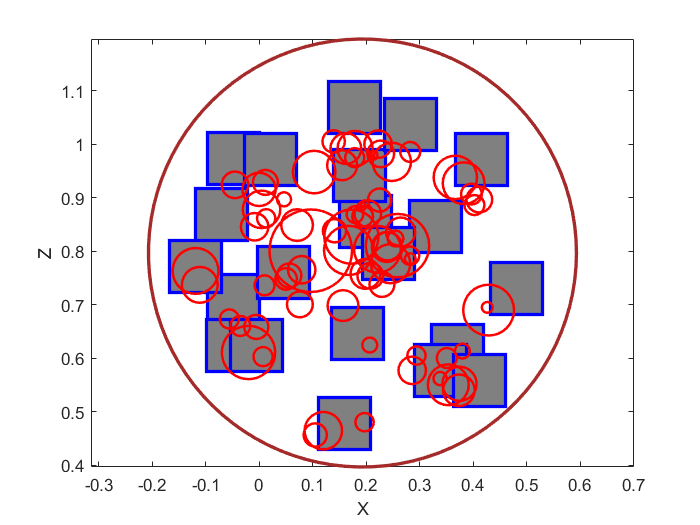

notTableL = ~(strcmp(fixationData.Object,"Table"));
figure()
plot(fixationData.PosX(notTableL), fixationData.PosZ(notTableL),'s',...
    'LineWidth',2,...
    'MarkerSize',40,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
hold on

for k=1:numel(fixationData.("No. Gaze Pts"))
  plot(fixationData.CentrX(k),fixationData.CentrZ(k),'ro',...
      'MarkerSize',fixationData.("No. Gaze Pts")(k)/2,...
      'LineWidth',1.5)
  hold on
end
set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
    'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
theta = linspace(0,2*pi);
x = (tableDiameter/2)*cos(theta) + tableX;
y = (tableDiameter/2)*sin(theta) + tableZ;
plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
xlabel('X')
ylabel('Z')
hold off
axis equal

fixation markers proportional to fixations per object, vector markers between fixation markers

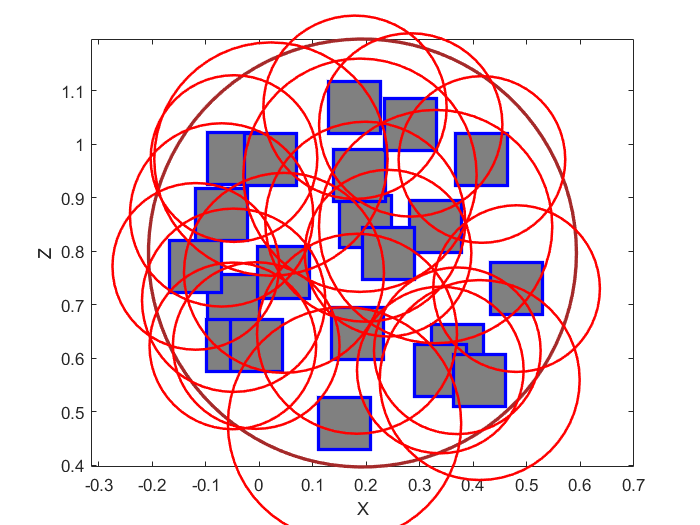

notTableL = ~(strcmp(fixationData.Object,"Table"));
notTableLObjID = ~(strcmp(objectIDs,"Table"));
figure()
plot(fixationData.PosX(notTableL), fixationData.PosZ(notTableL),'s',...
    'LineWidth',2,...
    'MarkerSize',40,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
hold on
set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
    'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
%plot scanpath between fixations

theta = linspace(0,2*pi);
x = (tableDiameter/2)*cos(theta) + tableX;
y = (tableDiameter/2)*sin(theta) + tableZ;
plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
xlabel('X')
ylabel('Z')

%plot fixation markers proportional to number of fixations per object
for i = 1: length(objectIDs(notTableLObjID)) %iterate per object  
    temp = fixationData(strcmp(fixationData.Object,objectIDs(i,1)),:);
    for j = 1:height(temp)
        plot(temp.PosX(j),temp.PosZ(j),'ro',...
      'MarkerSize',fixationVariables.(i)(1)*10,...
      'LineWidth',1.5)
        hold on       
    end
end
% for k=1:height(fixationData)
%     if k+1 <= height(fixationData) && fixationData.PosX(k) ~= fixationData.PosX(k+1)
%             arrow3([fixationData.CentrX(k) fixationData.CentrZ(k)],...
%             [fixationData.CentrX(k+1) fixationData.CentrZ(k+1)],'r--')
%     end
% end
axis equal

scanpath

notTableL = ~(strcmp(fixationData.Object,"Table"));
notTableLObjID = ~(strcmp(objectIDs,"Table"));
figure()
plot(fixationData.PosX(notTableL), fixationData.PosZ(notTableL),'s',...
    'LineWidth',2,...
    'MarkerSize',40,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])
hold on
set(gca,'XLim',[tableX-(tableDiameter/2) tableX+(tableDiameter/2)],...
    'YLim', [tableZ-(tableDiameter/2) tableZ+(tableDiameter/2)])
%plot scanpath between 

theta = linspace(0,2*pi);
x = (tableDiameter/2)*cos(theta) + tableX;
y = (tableDiameter/2)*sin(theta) + tableZ;
plot(x,y,'Color',[165/255,42/255,42/255],'LineWidth',2)
xlabel('X')
ylabel('Z')

%plot fixation markers proportional to number of fixations per object
% for i = 1: length(objectIDs(notTableLObjID)) %iterate per object  
%     temp = fixationData(strcmp(fixationData.Object,objectIDs(i,1)),:);
%     for j = 1:height(temp)
%         plot(temp.PosX(j),temp.PosZ(j),'ro',...
%       'MarkerSize',fixationVariables.(i)(1)*10,...
%       'LineWidth',1.5)
%         hold on       
%     end
% end
for k=1:height(fixationData)
    if k+1 <= height(fixationData) && fixationData.PosX(k) ~= fixationData.PosX(k+1)
            arrow3([fixationData.CentrX(k) fixationData.CentrZ(k)],...
            [fixationData.CentrX(k+1) fixationData.CentrZ(k+1)],'r--')
    end
end

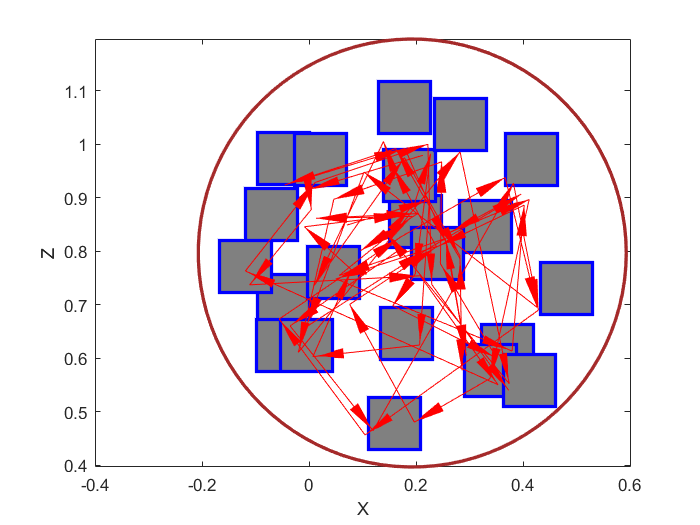

axis equal